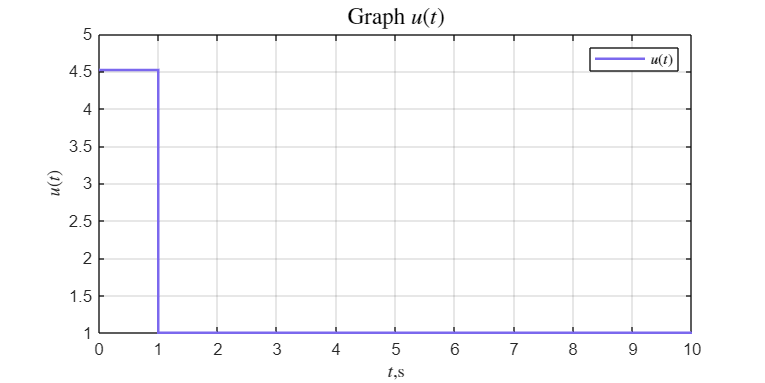

clear all;

a = 2;
b = 4;

f1 = exp(-0.25);
f2 = 1 - f1;

% Проверка теоретической передаточной функции
%{
HG = tf([0.2212], [1, -0.7788, 0, 0], 1); % Объект
D = tf([1, -0.7788, 0, 0], [0.2212, 0, 0, -0.2212], 1); % Регулятор

T = feedback(D * HG, 1);
step(T); grid on;
%}
%======================================================
% GRAPHICS
%======================================================

set_param('schem_1/y', 'VariableName', 'y');
set_param('schem_1/u', 'VariableName', 'u');


out = sim('schem_1');
y_ = out.y.Data;
t_ = out.y.Time;
u_ = out.u.Data;
tu_ = out.u.Time;

% Построение графика

% Определяем цвета для линий
a_color = '#00FFFF'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(tu_, u_, '-', 'LineWidth', 1.5, 'Color', b_color);

grid on;

title('Graph $u(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$u(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$u(t)$','Interpreter', 'latex')

hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_4\Discrete_report_4\pic\' ...
    '1_u.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

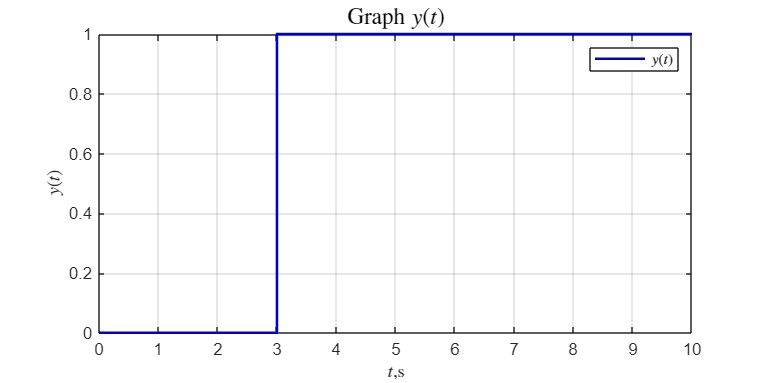



figure('Position', [100 100 800 400]);
stairs(t_, y_, '-', 'LineWidth', 1.5, 'Color', d_color);

grid on;

title('Graph $y(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$y (t)$','Interpreter', 'latex')

hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_4\Discrete_report_4\pic\' ...
    '1_y.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);